# Example 5: Field Case Study at the Dogger Geothermal Reservoir in the Paris Basin (France) - Part II

## Introduction

In the first part of this example, we demonstrated how to (i) simulate well catchments with injection and production wells, (ii) identify catchments for all connected injection-pumping well pairs within a flow field, and (iii) simulate forward and backward travel times throughout the aquifer. In this second part, we will illustrate how these simulated variables can be combined to perform additional quantitative analyses, as outlined in [[1](https://www.researchgate.net/publication/338175524_A_Dual_Delineation_Approach_to_Untangle_Interferences_in_Well_Doublets_Systems)]. Importantly, all derived variables are obtained through post-processing and do not require any further simulation. 

We load all variables from `example4.mat` back into the workspace. This file contains all variables generated by running the live script for the fourth example. If `example4.mat` is not available in the current directory or if the script hasn’t been run, please return to Example 4 and execute it. Once the file is ready, use the `load` function to read it into the workspace. 

load('example4.mat');

## Time-Dependent Contributing Zones

By applying simple post-processing to the outputs of the double delineation method (DDA), time-related capture zones for each pumping well can be determined. This is typically done by plotting iso-values from the spatial distribution of the travel time variable. As discussed in the first part of this example, DDA has an inherent advantage over particle tracking for this purpose. However, when multiple wells are pumping groundwater, a single delineation based on travel time iso-values may not adequately distinguish aquifer zones captured by specific wells. These distinct zones are known as contributing zones of capture. 

The double delineation approach can identify a pumping well’s contributing zone of capture at a specific time, $t_a$, by intersecting the well's catchment area with the iso-value of backward travel time at $t_a$. Since DDA is a grid-based method, this can be done efficiently by selecting grid cells within the well’s catchment that satisfy the condition $t \le t_a$. 

We define the `target_time` variable as the time at which we will extract the capture zone for pumping wells, the recharge zone for injection wells, and the contributing zones for injection-pumping well pairs. In this live script, this value can be selected using the slider control provided. All calculations in this section, including plots, will be instantly updated when a different value is selected. This interactivity facilitates the investigation of how capture, recharge, and contributing zones evolve over time. 

target_time =40;

At the target time, we initialize a grid cell index variable, `pump_well_index_t`, setting it equal to the pumping well catchment indices array, `pump_well_index`. For visualization of the pumping wells’ zones of capture, we create a new partition containing all indices in this array with backward travel times exceeding $t_a$. This partition will be blanked (i.e., displayed in white) to highlight the contributing capture zones more clearly. 

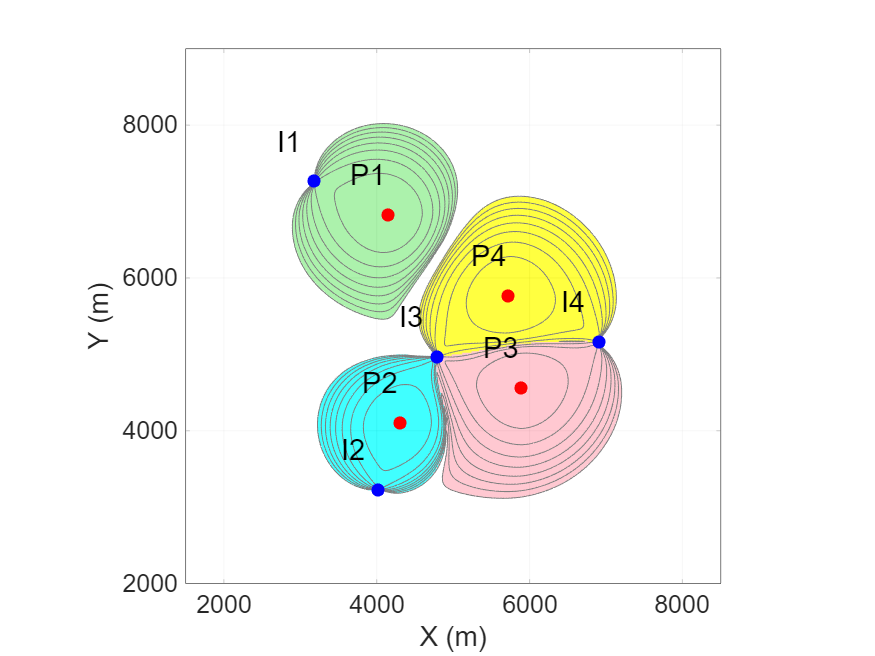

pump_well_index_t = pump_well_index;
pump_well_index_t(btt/year>target_time) = max(pump_well_index) + 1;

figure;
colors = rgb(Color,{'light green' 'aqua' 'light pink' 'yellow' 'white'});
colormap(colors);
plotCellData(G2D, pump_well_index_t, 'DataType', 'Index',...
    'EdgeColor', 'none', 'FaceAlpha', 0.75);
hold on;
opt.fill = 'off';
plotContourData(G2D,btt/year,opt,'LevelList',5:5:target_time,'LineColor',rgb(Color,'gray'));
axis tight equal; 
axis(1e3*[1.5,8.5,2,9]); 
grid on; 
colorbar off; 
box on;
ax = gca;
ax.XTick = 2000:2000:8000; ax.YTick = 2000:2000:8000;
xlabel('X (m)'); ylabel('Y (m)');
set(gca,'fontsize',12); 
scatter(xinj,yinj,40,'b','filled');
scatter(xpmp,ypmp,40,'r','filled');
text([xinj,xpmp]-500, [yinj,ypmp]+500, ... 
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, 'FontSize',14);
hold off;

As expected, the figure above shows the time-related capture zones for each pumping well in distinct colors, effectively distinguishing each well’s contribution to the overall capture zone.

Similarly, we identify an injection well’s contributing zone of capture at a specific time, $t_a$, by intersecting the well's catchment area with the iso-value of forward travel time at $t_a$. Since DDA is a grid-based method, this can be done efficiently by selecting grid cells within the well’s catchment that satisfy the condition $t \le t_a$.

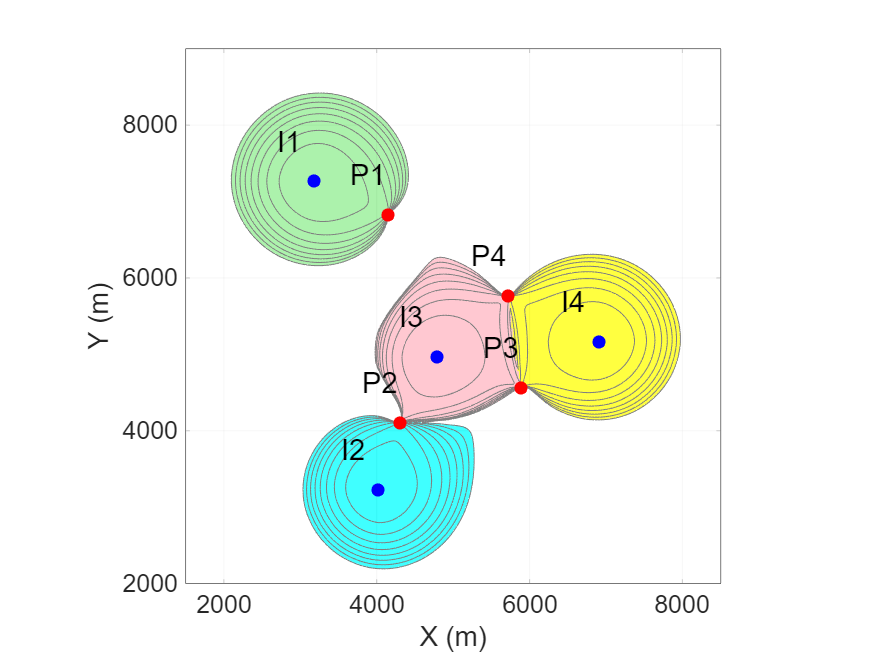

inj_well_index_t = inj_well_index;
inj_well_index_t(ftt/year>target_time) = max(inj_well_index) + 1;

figure;
colors = rgb(Color,{'light green' 'aqua' 'light pink' 'yellow' 'white'});
colormap(colors);
plotCellData(G2D, inj_well_index_t, 'DataType', 'Index',...
    'EdgeColor', 'none', 'FaceAlpha', 0.75);
hold on;
opt.fill = 'off';
plotContourData(G2D,ftt/year,opt,'LevelList',5:5:target_time,'LineColor',rgb(Color,'gray'));
axis tight equal; 
axis(1e3*[1.5,8.5,2,9]); 
grid on; 
colorbar off; 
box on;
ax = gca;
ax.XTick = 2000:2000:8000; ax.YTick = 2000:2000:8000;
xlabel('X (m)'); ylabel('Y (m)');
set(gca,'fontsize',12); 
scatter(xinj,yinj,40,'b','filled');
scatter(xpmp,ypmp,40,'r','filled');
text([xinj,xpmp]-500, [yinj,ypmp]+500, ... 
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, 'FontSize',14);
hold off;

The figure above shows the time-related recharge zones for each injection well in distinct colors, effectively distinguishing each well’s contribution to the overall recharge zone.

Next, we extract time-dependent interaction zones, representing the intersections between the time-related capture zones of pumping wells and the recharge zones of injection wells. These interaction zones are determined by post-processing the time-dependent partitions at the target time. 

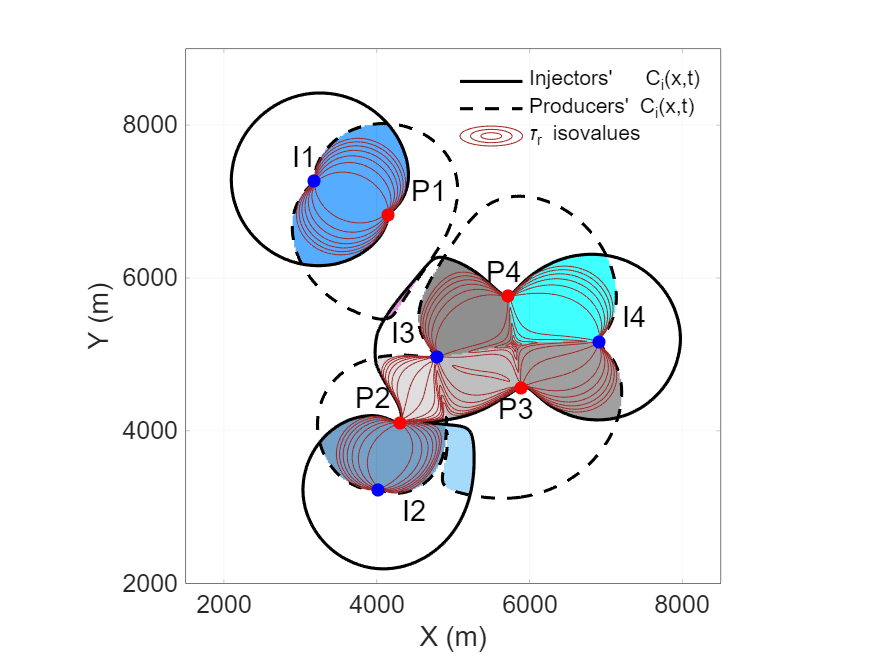

[well_pair_t,well_pair_index_t,well_pair_volume_t] = wellPairCatchments(Grid, inj_well_index_t, pump_well_index_t);
outer_idx = sort(unique([find(strcmp(well_pair_t(:,1), 'I5')); find(strcmp(well_pair_t(:,2), 'P5'))], 'stable'));
old_wp_length = length(well_pair_t);
well_pair_t(strcmp(well_pair_t(:,1), 'I5'),:) = [];
well_pair_t(strcmp(well_pair_t(:,2), 'P5'),:) = [];
for i = 1 : length(outer_idx)
   well_pair_index_t(well_pair_index_t == outer_idx(i)) = old_wp_length + 1;
end
well_pair_index_t = renumber_indices(well_pair_index_t);

figure;
colors=rgb(Color,{'light sky blue' 'steel blue' 'light gray' 'dark gray' 'gray' 'dim gray' 'aqua' 'orchid' 'dodger blue' 'white' });
colormap(colors); 
plotCellData(G2D, well_pair_index_t, 'DataType', 'Index',...
    'EdgeColor', 'none', 'FaceAlpha', 0.75);
hold on;
opt.fill = 'off';
plotContourData(G2D,ftt/year,opt,'LevelList',target_time,'LineColor','k','LineWidth',1.5);
plotContourData(G2D,btt/year,opt,'LevelList',target_time,'LineColor','k','LineStyle','--','LineWidth',1.5);
plotContourData(G2D,residence_time/year,opt,'LevelList',5:5:target_time,'LineColor',rgb(Color,'brown'),'LineWidth',0.5);
axis tight equal; 
axis(1e3*[1.5,8.5,2,9]); 
grid on; 
colorbar off; 
box on;
ax = gca;
ax.XTick = 2000:2000:8000; 
ax.YTick = 2000:2000:8000;
xlabel('X (m)'); 
ylabel('Y (m)');
set(gca,'fontsize',12); 
hinj = scatter(xinj,yinj,40,'b','filled');
hpmp = scatter(xpmp,ypmp,40,'r','filled');
x_off = [-300 +300 -600 +300 +300 -600 -300 -300];
y_off = [+300 -300 +300 +300 +300 +300 -300 +300];
text([xinj,xpmp]+x_off, [yinj,ypmp]+y_off, ... 
    {'I1','I2','I3','I4','P1','P2','P3','P4'}, 'FontSize',14);
lgd = legend('','Injectors''   C_i(x,t)','Producers'' C_i(x,t)','\tau_r isovalues','Location','northeast');
lgd.FontSize = 10;
legend('boxoff');
hold off;

The figure above is similar to Figure 3 in [[1](https://www.researchgate.net/publication/338175524_A_Dual_Delineation_Approach_to_Untangle_Interferences_in_Well_Doublets_Systems)], illustrating the extents and shapes of the contributing areas within the capture zones of pumping wells and the recharge zones of injection wells over time. It confirms that these areas fully encompass all streamlines that break through at shorter residence times. 

By decreasing or increasing the `target_time` variable defined above, we can more easily observe how the interaction zones shrink or expand, respectively. We can identify the number of well-pair connection zones, allowing us to detect critical times at which new interaction zones begin to form.

## Cumulative Pore Volume and Fractional Flow Rate

Another outcome derived from the DDA is the volumetric partitioning of groundwater across various streamtubes linking an injection well with a corresponding pumping well. To quantify this, we define the normalized cumulative pore volume between injection well i and pumping well j as a function of the increasing mean residence time:


$$\Phi_{ij}(\tau_r) = \frac {\int_0^{\tau_r} \phi(x(t)) dt} {\int_0^{+\infty} \phi(x(t)) dt}$$


where x(t) represents all streamtubes with a residence time equal to t. This corresponds to the ratio between the volume of injected fluid breaking through at a specific time, $\tau_r$, and the total pore volume of the same grid partition at infinite residence time. 

Similarly, the normalized cumulative flow rate between injection well i and pumping well j is expressed as a function of increasing mean residence time: 


$$F_{ij}^q(\tau_r) = \frac {\int_0^{\tau_r} q(t) dt} {\int_0^{\infty} q(t) dt}$$


where q(t) is the cell-centered flow rate at a mean residence time t. This represents the fractional flow rate at time $\tau_r$ indicating the fraction of injected fluid in the produced output. When this value reaches 1, it signifies that the pumping well can no longer produce resident fluid. 

To calculate $\Phi_{ij}(\tau_r)$ and $F_{ij}^q(\tau_r)$, we identify and sort all grid cells within the well pair partitions at increasing values of mean residence time. This straightforward procedure is illustrated here for the injection well I3 and the pumping wells P2, P3, and P4. 

 Next, we obtain the indices of the well pairs I3-P2, I3-P3 and I3-P4 in the array `well_pair_t`. 

idx_pair_I3_P2 = find(strcmp(well_pair_t(:,1),'I3') & strcmp(well_pair_t(:,2),'P2'));
idx_pair_I3_P3 = find(strcmp(well_pair_t(:,1),'I3') & strcmp(well_pair_t(:,2),'P3'));
idx_pair_I3_P4 = find(strcmp(well_pair_t(:,1),'I3') & strcmp(well_pair_t(:,2),'P4'));

Then, we locate the indices of the grid cells and count the number of cells in the partitions formed by these three well pairs. 

idx_part_I3_P2 = find(well_pair_index_t == idx_pair_I3_P2);
idx_part_I3_P3 = find(well_pair_index_t == idx_pair_I3_P3);
idx_part_I3_P4 = find(well_pair_index_t == idx_pair_I3_P4);
len_part32 = length(idx_part_I3_P2);
len_part33 = length(idx_part_I3_P3);
len_part34 = length(idx_part_I3_P4);

Next, we calculate the pore volume for all grid cells associated with these well pairs. 

pv32 = Grid.V * reshape(Grid.properties.porosity(idx_part_I3_P2),len_part32,1);
pv33 = Grid.V * reshape(Grid.properties.porosity(idx_part_I3_P3),len_part33,1);
pv34 = Grid.V * reshape(Grid.properties.porosity(idx_part_I3_P4),len_part34,1);

Finally, we call the function `computeCumulativePhiQ`, which calculates the cumulative pore volume and fractional flow rate for increasing values of mean residence time in each well pair partition.  

[rt32,cumPhi32,cumQ32] = computeCumulativePhiQ(pv32, residence_time(idx_part_I3_P2));
[rt33,cumPhi33,cumQ33] = computeCumulativePhiQ(pv33, residence_time(idx_part_I3_P3));
[rt34,cumPhi34,cumQ34] = computeCumulativePhiQ(pv34, residence_time(idx_part_I3_P4));

Now, it is straightforward to plot the cumulative pore volume against mean residence time for the well pairs I3-P2, I3-P3 and I3-P4. 

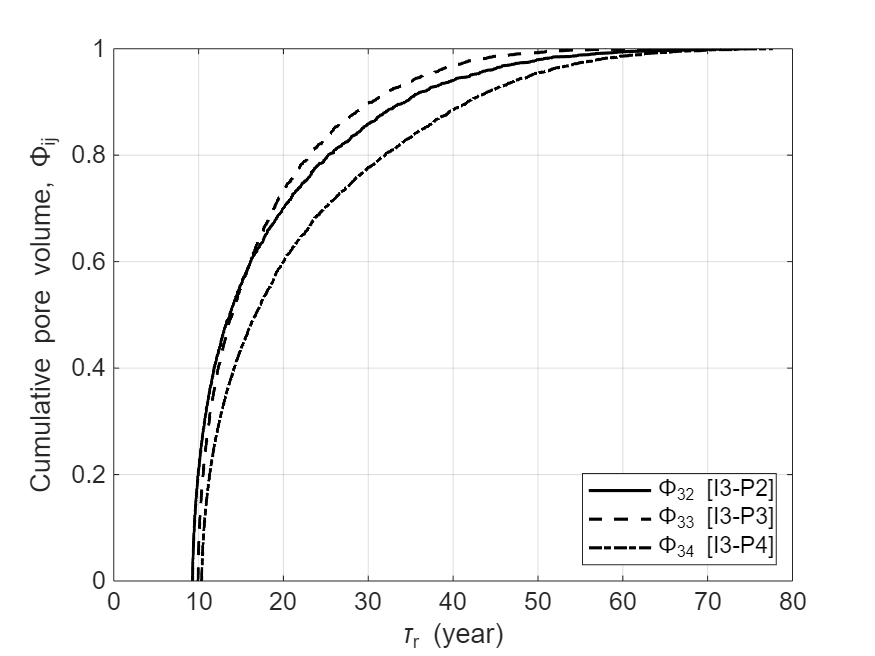

figure;
plot(rt32/year,cumPhi32,'k-', 'LineWidth',1.5);
hold on, 
plot(rt33/year,cumPhi33,'k--','LineWidth',1.5);
plot(rt34/year,cumPhi34,'k-.','LineWidth',1.5);
hold off;
axis([0, 80, 0, 1]); 
grid on;
ax = gca;
ax.XTick = 0:10:80; 
ax.YTick = 0:0.2:1;
xlabel('\tau_r (year)'); 
ylabel('Cumulative pore volume, \Phi_{ij}');
legend('\Phi_{32} [I3-P2]','\Phi_{33} [I3-P3]','\Phi_{34} [I3-P4]','Location','southeast');
set(gca,'fontsize',12);

Next, we will plot the cumulative fractional flow rate against mean residence time for the same well pairs.

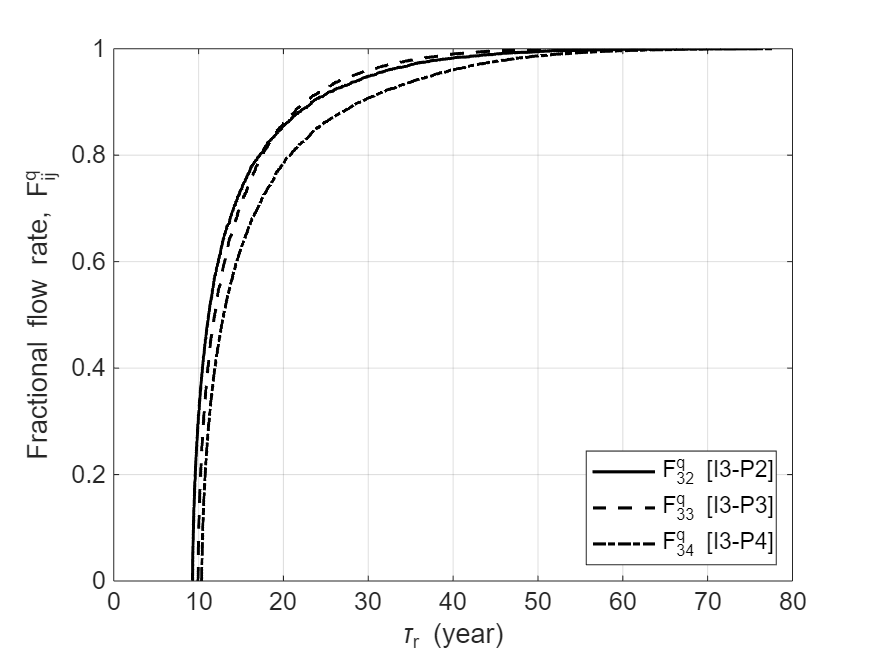

figure;
plot(rt32/year,cumQ32,'k-', 'LineWidth',1.5);
hold on, 
plot(rt33/year,cumQ33,'k--','LineWidth',1.5);
plot(rt34/year,cumQ34,'k-.','LineWidth',1.5);
hold off;
axis([0, 80, 0, 1]); 
grid on;
ax = gca;
ax.XTick = 0:10:80; 
ax.YTick = 0:0.2:1;
xlabel('\tau_r (year)'); 
ylabel('Fractional flow rate, F_{ij}^q');
legend('F_{32}^q [I3-P2]','F_{33}^q [I3-P3]','F_{34}^q [I3-P4]','Location','southeast');
set(gca,'fontsize',12);

The last two figures are identical to Figures 4-a and 4-b in reference [[1](https://www.researchgate.net/publication/338175524_A_Dual_Delineation_Approach_to_Untangle_Interferences_in_Well_Doublets_Systems)].

## Allocated Flow Rate Fractions to Pumping Wells

We define the allocated flow rate fraction at time t for pumping well j from injection well i as follows: 


$$F_{ij}^q = \frac{PV_{ij}(t)}{\sum_j PV_{ij}(t)}$$


where $PV_{ij}(t)$ is the pore volume of the contributing zone of well pair i-j. The sum in the denominator represents the pore volume of the capture zone for well j at time t. The allocated flow rate fraction represents the portion of the injected groundwater volume that will be extracted by another well.

In this section, we focus on injection well I3 and calculate the evolution of the allocated fractional flow rate from this well to all pumping wells. First, we define a discrete time array over which the volume of each contributing zone will be calculated. The helper function `well_pair_volume` determines the time-dependent evolution of the contributing zone volume between any pair of injection and production wells. Finally, we compute the total volume array, `vol3`, for the capture zone of I3.

t = 1:1:100;
[~,vol31] = well_pair_volume(Grid, inj_well_index, pump_well_index, ftt, btt, [3 1], t, year);
[~,vol32] = well_pair_volume(Grid, inj_well_index, pump_well_index, ftt, btt, [3 2], t, year);
[~,vol33] = well_pair_volume(Grid, inj_well_index, pump_well_index, ftt, btt, [3 3], t, year);
[~,vol34] = well_pair_volume(Grid, inj_well_index, pump_well_index, ftt, btt, [3 4], t, year);
vol3 = vol31 + vol32 + vol33 + vol34;

Calculate the ratios according to the above equation.

r_31 = vol31./vol3;
r_32 = vol32./vol3;
r_33 = vol33./vol3;
r_34 = vol34./vol3;

Plot the evolution of the allocated flow rate fractions from injection well I3 to production wells P1 through P4.

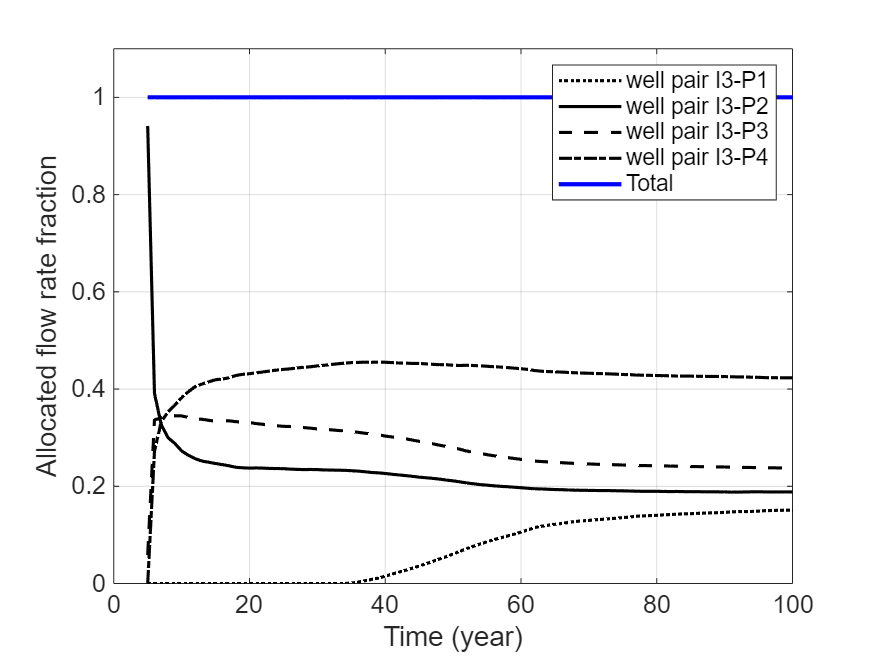

figure;
plot(t,r_31,'k:','LineWidth',1.5);
hold on;
plot(t,r_32,'k-','LineWidth',1.5);
plot(t,r_33,'k--','LineWidth',1.5);
plot(t,r_34,'k-.','LineWidth',1.5);
plot(t,r_31+r_32+r_33+r_34,'b-','LineWidth',2);
hold off;
ylim([0 1.1]);
xlabel('Time (year)'); 
ylabel('Allocated flow rate fraction'); 
legend('well pair I3-P1','well pair I3-P2','well pair I3-P3','well pair I3-P4','Total','Location','northeast');
grid on; 
set(gca,'fontsize',12);

Notably, this figure closely resembles Figure 4-c in [[1](https://www.researchgate.net/publication/338175524_A_Dual_Delineation_Approach_to_Untangle_Interferences_in_Well_Doublets_Systems)]. It illustrates the time-dependent hierarchy of allocated flow rate fractions from injection well I3 to all pumping wells. In particular, this ranking is maintained over time. For instance, except in the initial years when P2 attracts the majority of the injected groundwater, more than 40% and 30% of the total volume are allocated to P4 and P3, respectively.

## Thermal Decline at Production Wells

In this section, we evaluate the thermal decline profile at production well P2, which extracts hot water from the reservoir at the initial temperature, $T_{ini}$, using the mixing formula:


$$T(\tau_r^*) = \frac{\sum_{i=1}^{N_i} Q_i(F_{ij}^q(\tau_r^*)T_{inj}+(1-F_{ij}^q(\tau_r^*)T_{ini})} {\sum_{i=1}^{N_i} Q_i} $$
 

where, $N_i$, is the number of connected injection wells, $Q_i$, are injection flow rates, $F_{ij}^q(\tau_r^*)$ are the cumulative fractional flow rate at the thermal residence time $\tau_r^*$, between injection well i and production well j, and $T_{inj} < T_{ini}$ is the temperature of injected cold water.  

To prepare these calculations, we first obtain the index of the well doublet I2-P2 in the `well_pair_t` array, then retrieve all grid cell indices associated with the partition created by this doublet in the `idx_part_I2_P2` array.  

idx_pair_I2_P2 = find(strcmp(well_pair_t(:,1),'I2') & strcmp(well_pair_t(:,2),'P2'));
idx_part_I2_P2 = find(well_pair_index_t == idx_pair_I2_P2);
len_part22 = length(idx_part_I2_P2);

Next, we calculate the pore volume of the I2-P2 partition and determine the associated cumulative pore volumes and fractional flow rates.

pv22 = Grid.V * reshape(Grid.properties.porosity(idx_part_I2_P2),len_part22,1);
[rt22,cumPhi22,cumQ22] = computeCumulativePhiQ(pv22, residence_time(idx_part_I2_P2));

We define the initial and injection temperatures, as well as the thermal retardation factor of the formation. Then, we calculate the mixing temperature using the formula provided above.

T_ini = 77.6;
T_inj = 50;
R_th  = 3;
Tmix_I2  = T_ini*(ones(size(cumQ22))-cumQ22) + T_inj*cumQ22;
Tmix_I3  = T_ini*(ones(size(cumQ32))-cumQ32) + T_inj*cumQ32; 

Since the temperature decline arrays from wells I2 and I3 may have different lengths, we first interpolate these arrays onto a uniformly spaced time array from 0 to 90 years. The overall temperature decline, `Tmix`, is then calculated on this time array using a mixing rule, with injection flow rates as weighting factors. 

x = (0:0.5:90) * year;
Tmix_I2_interp = interp1([0;R_th*rt22], [T_ini;Tmix_I2], x, 'pchip');
Tmix_I3_interp = interp1([0;R_th*rt32], [T_ini;Tmix_I3], x, 'pchip');
Tmix = (Q2*Tmix_I2_interp + Q1*Tmix_I3_interp) / (Q1+Q2);

Finally, we plot three curves that illustrate the overall temperature decline in the production well, along with the relative contributions to this decline from injection wells I2 and I3.

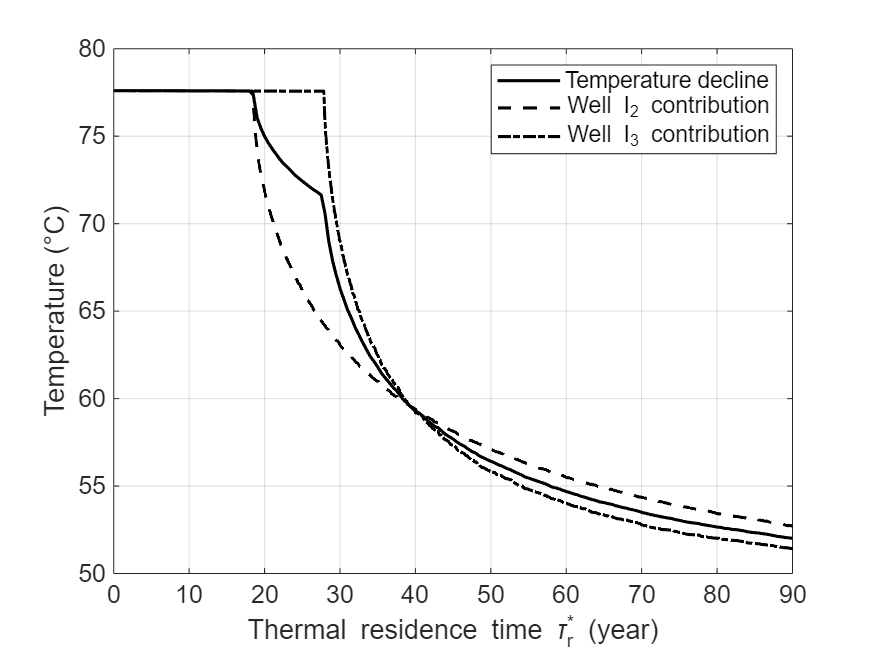

figure; 
plot(x/year, Tmix, 'k-', 'LineWidth', 1.5);
hold on;
plot([0;R_th*rt22/year], [T_ini;Tmix_I2], 'k--', 'LineWidth',1.5);
plot([0;R_th*rt32/year], [T_ini;Tmix_I3], 'k-.', 'LineWidth', 1.5);
hold off;
grid on;
ax = gca;
ax.XTick = 0:10:90; 
ax.YTick = 20:5:80;
ax.XLim = [0 90]; 
ax.YLim = [50 80];
xlabel('Thermal residence time \tau_r^* (year)'); 
ylabel('Temperature (°C)');
legend('Temperature decline','Well I_2 contribution','Well I_3 contribution');
set(gca,'fontsize',12);

The figure above, akin to Figure 5 in [[1](https://www.researchgate.net/publication/338175524_A_Dual_Delineation_Approach_to_Untangle_Interferences_in_Well_Doublets_Systems)], illustrates the relative contributions of injection wells I2 and I3 to the overall thermal decline at production well P2. An early heat breakthrough from injection well I2 occurs at 18.5 years, followed by that of I3 at 29.85 years. As a result, the temperature decline steepens significantly compared to the initial period, making geothermal heat extraction barely economical after 30 years of the doublet's operational life. 

This is a significant outcome of the DDA, based on the simplifying assumptions that heat advection dominates over thermal mechanical processes, diffusive dispersion, and heat conduction. Although advanced coupled heat and transport models are more complex, they do not provide direct insights into the relative contributions of other injection wells to the overall temperature decline profile. This information is particularly crucial for designing the placement and flow rates of new doublets. 

## Discussion 

The results of our analysis highlight the effectiveness of the double delineation approach (DDA) in characterizing the spatial and temporal dynamics of groundwater systems involving injection and production wells. By utilizing time-dependent contributing zones, we can discern how capture zones evolve over time, providing critical insights for groundwater management and resource allocation.

The ability to define contributing zones of capture for each pumping well at specific times is particularly noteworthy. This not only enhances our understanding of individual well contributions but also allows for a more nuanced view of aquifer behavior under varying operational scenarios. The interactive visualization of capture and recharge zones serves as a powerful tool for real-time analysis, enabling stakeholders to adapt their strategies based on evolving conditions.

Moreover, our examination of cumulative pore volume and fractional flow rates underscores the importance of quantifying groundwater flow dynamics between injection and production wells. By establishing normalized values for cumulative pore volume and fractional flow rates as functions of mean residence time, we provide a quantitative framework for evaluating the efficiency of groundwater extraction and the potential for resource depletion. The maintenance of allocated flow rate fractions over time reveals a consistent hierarchy of groundwater allocation, emphasizing the need for careful monitoring and management of interconnected well pairs.

The thermal decline analysis at production wells introduces an additional dimension to our findings, illustrating the interplay between groundwater extraction and thermal properties of the reservoir. The mixing formula employed offers a practical means to assess thermal performance, showcasing how the contributions from various injection wells affect the thermal output of production wells. This aspect is crucial for optimizing geothermal resource extraction and ensuring economic viability over time.

While the DDA provides valuable insights, it is essential to recognize the simplifying assumptions underlying our model, particularly the dominance of heat advection over other thermal processes. Future studies could benefit from integrating more sophisticated coupled heat and transport models to capture the complex interactions within groundwater systems more comprehensively. Such advancements would facilitate the refinement of management practices, ultimately leading to more sustainable and effective use of geothermal and groundwater resources.

In conclusion, the combined use of DDA, time-dependent analyses, and thermal decline assessments offers a robust framework for understanding the dynamics of groundwater systems. These insights can inform the design and operation of injection-pumping well systems, enhancing their efficiency and sustainability in the long term.

## References

[1] [Sbai, M.A. (2020); A Dual Delineation Approach to Untangle Interferences in Well Doublets Systems. Groundwater, 58(5), 822-830. http://dx.doi.org/10.1111/gwat.12978](https://www.researchgate.net/publication/338175524_A_Dual_Delineation_Approach_to_Untangle_Interferences_in_Well_Doublets_Systems)

Author: M.A. Sbai, Ph.D.

Copyright (C) 2024 Mohammed Adil Sbai

This program is free software: you can redistribute it and/or modify it under the terms of the GNU General Public License as published by the Free Software Foundation, either version 3 of the License, or (at your option) any later version.

This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE. See the GNU General Public License for more details.

You should have received a copy of the GNU General Public License along with this program. If not, see <http://www.gnu.org/licenses/>.

function A_renumbered = renumber_indices(A)
    % RENNUMBER_INDICES Renumbers elements of A to be consecutive starting from 1
    % 
    % Input:
    %   A - n-by-1 array of strictly positive integer indices
    %
    % Output:
    %   A_renumbered - n-by-1 array with renumbered indices starting from 1
    
    % Step 1: Find unique indices in A and sort them
    unique_indices = unique(A);
    k = numel(unique_indices); % Number of unique indices used in A

    % Step 2: Create a mapping from original indices to new consecutive indices
    new_index_map = zeros(max(A), 1); % Preallocate for speed
    new_index_map(unique_indices) = 1:k;

    % Step 3: Replace each element in A with its new index
    A_renumbered = new_index_map(A);
end


function [t, vol] = well_pair_volume(G, inj_well_index, pump_well_index, ftt, btt, pair, times, year)
% well_pair_volume Computes the volume of groundwater between an injection and pumping well pair over specified time periods.
%
%   [t, vol] = well_pair_volume(G, inj_well_index, pump_well_index, ftt, btt, pair, times) takes the following input parameters:
%
%   Input Arguments:
%   G                     : A structure representing the grid information, which includes properties such as the number of edges (ne).
%   inj_well_index        : A vector containing indices of the injection wells.
%   pump_well_index       : A vector containing indices of the pumping wells.
%   ftt                   : A vector of forward travel times associated with each injection well (in seconds).
%   btt                   : A vector of backward travel times associated with each pumping well (in seconds).
%   pair                  : A 1x2 vector indicating the specific well pair, where pair(1) is the index of the injection well
%                          and pair(2) is the index of the pumping well.
%   times                 : A 1xN vector of time values (in years) at which to compute the well pair volumes.
%   year                  : The number of seconds in a year used for time conversion.
%
%   Outputs:
%   t                     : The input time values, returned for reference.
%   vol                   : A vector containing the computed volumes of groundwater between the specified well pair at each time in `times`.
%
%   Notes:
%   - The function assumes that the input vectors `inj_well_index` and `pump_well_index` are of the same length, 
%     corresponding to the number of edges in the grid G.
%   - Time values in `ftt` and `btt` are provided in seconds, while `times` is provided in years.
%   - The function filters out any well pair data associated with well 'I5' or 'P5' as part of its processing.
%   - The result for each time in `times` is calculated by checking the well pair's state at that time.
%
%   Example usage:
%       G = load('gridData.mat'); % Load grid data
%       inj_well_index = [1, 2, 3]; % Injection well indices
%       pump_well_index = [4, 5, 6]; % Pumping well indices
%       ftt = [100, 200, 300]; % Forward travel times in seconds
%       btt = [400, 500, 600]; % Backward travel times in seconds
%       pair = [1, 4]; % Well pair (Injection well 1 and Pumping well 4)
%       times = [1, 5, 10]; % Time in years
%       [t, vol] = well_pair_volume(G, inj_well_index, pump_well_index, ftt, btt, pair, times);
%
%   Author: M.A. Sbai, Ph.D.

   % Assertions to validate input dimensions and sizes
   assert(length(inj_well_index) == G.ne, 'Inconsistent length of inj_well_index with the grid.');
   assert(length(pump_well_index) == G.ne, 'Inconsistent length of pump_well_index with the grid.');
   assert(length(pair) == 2, 'Pair should contain exactly two elements.');
   assert(size(pair, 1) == 1, 'Pair should be a single row vector.');
   assert(size(times, 1) == 1, 'Times should be a single row vector.');

   % Define well names based on the provided indices
   inj_name = ['I' num2str(pair(1, 1))]; % Name of the injection well
   pmp_name = ['P' num2str(pair(1, 2))]; % Name of the pumping well

   % Initialize output variables
   t   = times; % Store input times
   vol = zeros(length(t), 1); % Preallocate volume array

   % Loop through each specified time to compute volumes
   for it = 1:length(t)

      % Update indices for injection and pumping wells based on travel times
      inj_well_index_t = inj_well_index;
      inj_well_index_t(ftt / year > t(it)) = max(inj_well_index) + 1;

      pump_well_index_t = pump_well_index;
      pump_well_index_t(btt / year > t(it)) = max(pump_well_index) + 1;

      % Obtain well pair data and corresponding volume
      [well_pair_t, ~, well_pair_volume_t] = ...
          wellPairCatchments(G, inj_well_index_t, pump_well_index_t);

      % Exclude data for well 'I5' and 'P5'
      well_pair_volume_t(strcmp(well_pair_t(:, 1), 'I5') | ...
                         strcmp(well_pair_t(:, 2), 'P5')) = [];
      well_pair_t(strcmp(well_pair_t(:, 1), 'I5'), :) = [];
      well_pair_t(strcmp(well_pair_t(:, 2), 'P5'), :) = [];

      % Find the index for the current well pair
      id = find(strcmp(well_pair_t(:, 1), inj_name) & strcmp(well_pair_t(:, 2), pmp_name));
      if ~isempty(id)
         vol(it) = well_pair_volume_t(id); % Store the volume for this time point
      end

   end

end
